%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 150000*0.946

W = 141900


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000


%Planform Parameters
S = 1875; %ft^2
AR = 7.43

AR = 7.4300

TaperRatio = 0.6;
b = sqrt(AR*S)

b = 118.0307

Q = 1.01

Q = 1.0100

SweepQuartC = 0;
e = 0.9;

%Fuselage Parameters
Df = 20.6; %ft
LNose = 8.33; %ft
LMid = 42; %ft
LTail = 44.5 %ft

LTail = 44.5000

UpsweepAngle = 0.1757; %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 590.8000

M = 0.5817

Cr = 19.8571

Cmac = 16.2166

Ymac = 27.0487

SweepMaxT = -1.1566

Cf = 18.4708

Sexp = 1.4802e+03

Re = 5.3494e+07

SweepMaxT = -1.1566

FF = 1.5504

Swet = 3.0419e+03

CDo = 0.0057


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 590.8000

M = 0.5817

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Cf = 11.6939

Sexp = 400

Re = 2.8050e+07

SweepMaxT = -1.7183

FF = 1.4906

Swet = 815.7600

CDo = 0.0079


CDoHt = CDoHt*Sh/S

CDoHt = 0.0017


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 590.8000

M = 0.5817

Cr = 8.4171

Cmac = 6.7066

Ymac = 10.3846

SweepMaxT = -0.9437

Cf = 8.4171

Sexp = 300

Re = 2.2123e+07

SweepMaxT = -0.9437

FF = 1.4907

Swet = 611.8200

CDo = 0.0082


CDoVt = CDoVt*Sv/S/2

CDoVt = 6.5469e-04


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

FF = 1.6266

CDoFuse = 0.0086


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0088


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag

CDoTotal = 0.0254


%Induced Drag Factor
% [TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
% AirDens = DensRat*2.3769*10^-3; %Slug/ft^3
% V=V*1.688
% M = V/SpeedSound
% 
% Ne = 0; %Num of engines ON TOP of Wing
% TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)
% K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)

K = 1/(e*pi*AR)

K = 0.0476


CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD =     0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275    0.0273    0.0272    0.0270    0.0268    0.0267    0.0265    0.0264    0.0262    0.0261    0.0260    0.0259    0.0258    0.0257    0.0257    0.0256    0.0256    0.0255    0.0255    0.0255    0.0254


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 0.3931

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 0.7858

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 1.1776

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 1.5681

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 1.9568

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 2.3434

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 2.7274

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 3.1083

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 3.4859

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 3.8597

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 4.2294

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 4.5945

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 4.9548

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 5.3099

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 5.6596

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 6.0035

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 6.3413

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 6.6729

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 6.9979

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 7.3162

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 7.6275

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 7.9318

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 8.2288

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 8.5183

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 8.8004

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 9.0749

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 9.3417

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 9.6007

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 9.8519

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 10.0953

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 10.3309

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 10.5586

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 10.7785

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 10.9907

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 11.1951

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 11.3918

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 11.5809

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 11.7624

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 11.9365

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 12.1033

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 12.2628

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 12.4152

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 12.5606

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 12.6991

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 12.8308

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 12.9559

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.0745

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.1868

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.2929

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.3930

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.4872

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.5756

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.6584

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.7359

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.8080

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.8750

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.9370

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 13.9942

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.0467

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.0947

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.1383

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.1777

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.2130

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.2443

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.2719

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.2957

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.3160

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.3328

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.3464

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.3568

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.3642

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.3686

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


LDMax = 14.3703

CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


CD = 1×30
    0.0373    0.0369    0.0364    0.0359    0.0355    0.0351    0.0346    0.0342    0.0338    0.0334    0.0330    0.0327    0.0323    0.0319    0.0316    0.0313    0.0309    0.0306    0.0303    0.0300    0.0297    0.0294    0.0292    0.0289    0.0287    0.0284    0.0282    0.0280    0.0277    0.0275


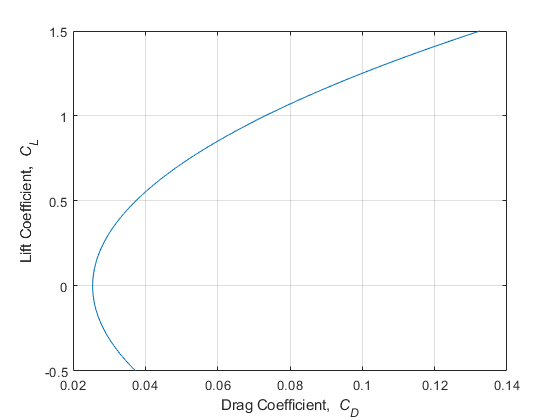


plot (CD,CL)
xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on


LDMax

LDMax = 14.3703